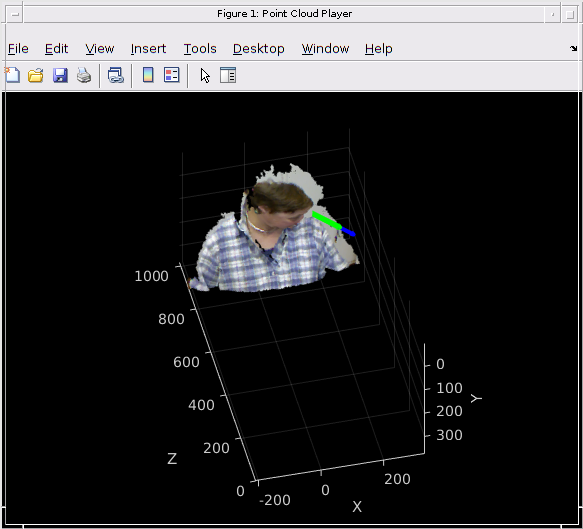

% Dataset
facesRoot = '/mnt/large/dataset/Biwi/kaggle_version3/faces_0/';

% Output root of this repo
truth2Dir = "/mnt/large/dataset/Biwi/BIWI_Matlab_Output";

% Show this image
imgPath = '/mnt/large/dataset/Biwi/kaggle_version3/faces_0/01/frame_00340_rgb.png';

% Deconstruct the file path for later use
[path, imgBasename, imgExt] = fileparts(imgPath);
basenameParts = split(imgBasename, '_');
imgStem = join(basenameParts(1:2, 1), '_');
imgStem = imgStem{1, 1}; % frame_00000
pathParts = split(path, '/');
imgDir = pathParts{end, 1}; % 01

img = imread(imgPath);

% Load the point cloud
load(fullfile(truth2Dir, sprintf("%s/%s_truth.mat", imgDir, imgStem)));
load(fullfile(truth2Dir, sprintf("%s/%s_ptcld.mat", imgDir, imgStem)));

% Prepare data for point cloud player
range_x = [min(pt_cld.x, [], 'all'), max(pt_cld.x, [], 'all')];
range_y = [min(pt_cld.y, [], 'all'), max(pt_cld.y, [], 'all')];
range_z = [min(pt_cld.z, [], 'all'), max(pt_cld.z, [], 'all')];

[row_is, col_is] = find(ones(size(pt_mask)));

n_points = length(row_is);
points = zeros(n_points, 3);
colors = zeros(n_points, 3, 'uint8');

for i = 1:length(row_is)
    row = row_is(i);
    col = col_is(i);
    points(i, 1) = pt_cld.x(row, col);
    points(i, 2) = pt_cld.y(row, col);
    points(i, 3) = pt_cld.z(row, col);
    colors(i, 1) = pt_cld.rgb(row, col, 1);
    colors(i, 2) = pt_cld.rgb(row, col, 2);
    colors(i, 3) = pt_cld.rgb(row, col, 3);
end

pc = pointCloud(points, 'Color', colors);

player = pcplayer(range_x, range_y, range_z, 'VerticalAxis','Y', 'VerticalAxisDir','Down');
% movegui(player.Axes, 'northwest');
view(player, pc);

% Ground truth location and orientation of the head from the .bin files
loc = gt_loc;
ang = gt_ang;
rot = rotx(ang(1)) * roty(ang(2)) * rotz(ang(3));
pino = rot * [0; 0; -1];

% Ground truth location and orientation of the head from the _pose.txt
poseTxt = replace(imgPath, "_rgb.png", "_pose.txt");
poseTxt = readmatrix(poseTxt);
poseRot = poseTxt(1:3, 1:3);
poseLoc = poseTxt(4, 1:3);
poseAng = rad2deg(rotm2eul(poseRot, 'zyx'));
poseAng = poseAng(end:-1:1);
poseRot = rotx(poseAng(1)) * roty(poseAng(2)) * rotz(poseAng(3));
posePino = poseRot * [0; 0; -1];

% Plot loc and rot in blue
hold(player.Axes, 'on');
if exist('arrow', 'var')
    delete(arrow);
end
arrow = quiver3( ...
    player.Axes, ...
    loc(1), loc(2), loc(3), ...
    pino(1), pino(2), pino(3), ...
    200, ...
    'Color', 'blue', ...
    'LineWidth', 3, 'Marker', '*', 'ShowArrowHead', 'on' ...
);

% Plot poseLoc and poseRot in green
if exist('poseArrow', 'var')
    delete(poseArrow)
end
poseArrow = quiver3( ...
    player.Axes, ...
    poseLoc(1), poseLoc(2), poseLoc(3), ...
    posePino(1), posePino(2), posePino(3), ...
    150, ...
    'Color', 'green', ...
    'LineWidth', 4, 'Marker', '*', 'ShowArrowHead', 'on' ...
);